## Load calcium mask from suite2p (from Fall.mat)

m=0;
NCell=sum(iscell(:,1)>0);

for n=1 : length(stat)

    if iscell(n,1)==1
        m=m+1;

        outline_gcampx(m)={double(stat{1, n}.xext+1)};
        outline_gcampy(m)={double(stat{1, n}.yext+1)};

        neuropil(m)={stat{1, n}.neuropil_mask};

        Coomasqx(m)={double(stat{1, n}.xpix+1)};%+1  to adpat suite2p output   ONLY 1 ??????
        Coomasqy(m)={double(stat{1, n}.ypix+1)};

    end

end

    colors = [
    1 0 0;     % Red
    0 1 0;     % Green
    0 0 1;     % Blue
    1 1 0;     % Yellow
    1 0 1;     % Magenta
    0 1 1;     % Cyan
    0.5 0 0;   % Maroon
    0 0.5 0;   % Olive
    0 0 0.5;   % Navy
    0.5 0.5 0; % Olive Green
    0.5 0 0.5; % Purple
    0 0.5 0.5; % Teal
    0.75 0 0;  % Dark Red
    0 0.75 0;  % Lime Green
    0 0 0.75;  % Dark Blue
    0.75 0.75 0; % Dark Yellow
    0.75 0 0.75; % Dark Magenta
    0 0.75 0.75; % Dark Cyan
];



idassembly=zeros(NCell,1);
listcellassembly=[];
assembly=assemblyortho;
%assembly=assemblystat;
%assembly=assemblyraw;
nbassemblies=length(assembly);

for n=1:nbassemblies
    idassembly(assemblyortho{n})=n;
    listcellassembly=[listcellassembly assemblyortho{n}];
    sumSCEpercluster(n)=sum(IDX2==n);
end

NCl = max(IDX2);
[~,x2] = sort(IDX2);
MSort = M(x2,x2);

% figure
% 
% % imagesc(calcium);
% % colormap (gray)
% % clim ([0 300])
% 
% hold on
% 
% for n=11:NCell
% 
%     x=cell2mat(outline_gcampx(n));
%     y=cell2mat(outline_gcampy(n));
% 
%     plot(x, y, '.', 'MarkerSize', 4,"Color",colors(idassembly(n),:));
%    % text(max(x),max(y),num2str(n),"FontSize",8,"Color",'w')
% end
% axis image
% axis off
% hold off
% title ('calcium')
% hold off

background=zeros(512,512);
figure
image(background);


for num=1:nbassemblies
    for n=cell2mat(assembly(num))
            x=cell2mat(outline_gcampx(n));
            y=cell2mat(outline_gcampy(n));
            sorted_indices = convhull(x, y); 
            x = x(sorted_indices);
            y = y(sorted_indices);
            patch(x, y,'k','FaceAlpha', 1,'EdgeColor',colors(num,:),'LineWidth',1)
             % patch(x, y,'w','FaceAlpha', 0.5,'EdgeColor',colors(num,:),'LineWidth',1)
            % text(max(x),max(y),num2str(n),"FontSize",8,"Color",'w')
            % plot(x, y, '.', 'MarkerSize', 4,"Color",col);
    end

    % hold on
end
colormap (gray)
axis off
axis image
% hold off

k=0

k = 0

for i = 1:NClOK
    if length(find(CellClraw(i,:)))>5 % is this the limit of cell per assembly ???it seems
        k = k+1;
        assembly_nonortho{k} = find(CellClraw(i,:));
    end
end
% assembly_nonortho=C0;


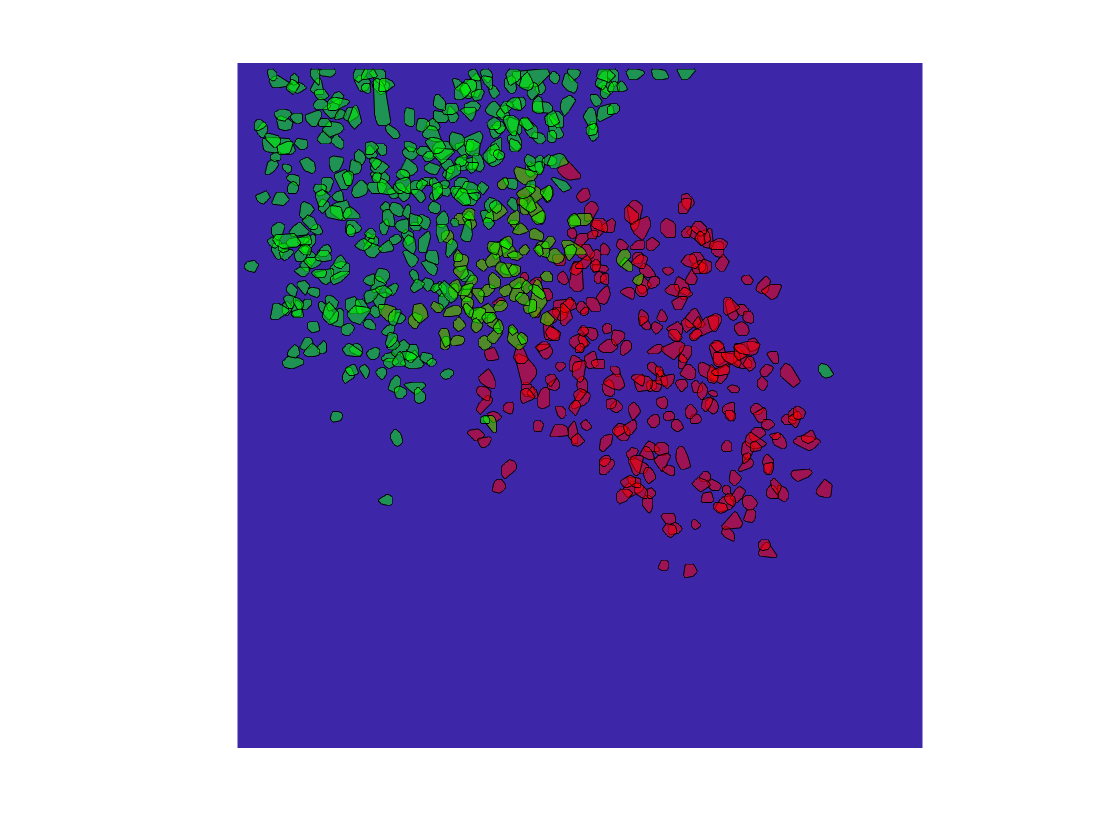

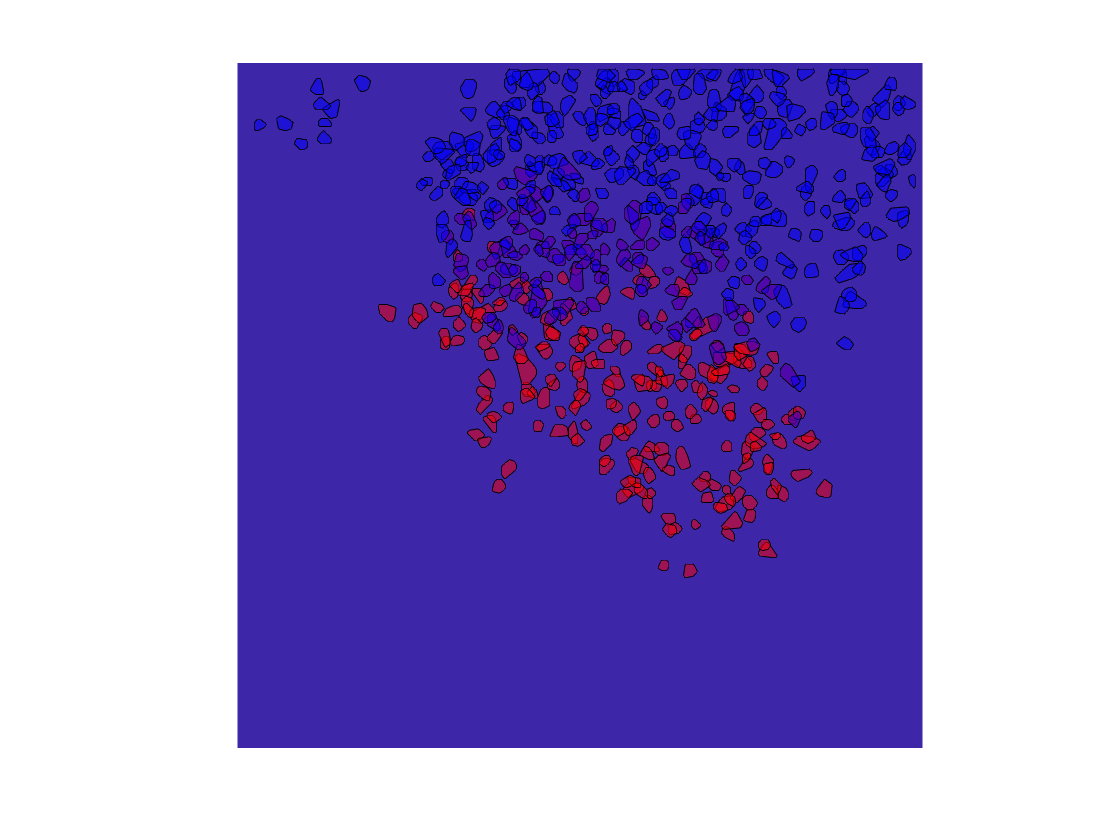

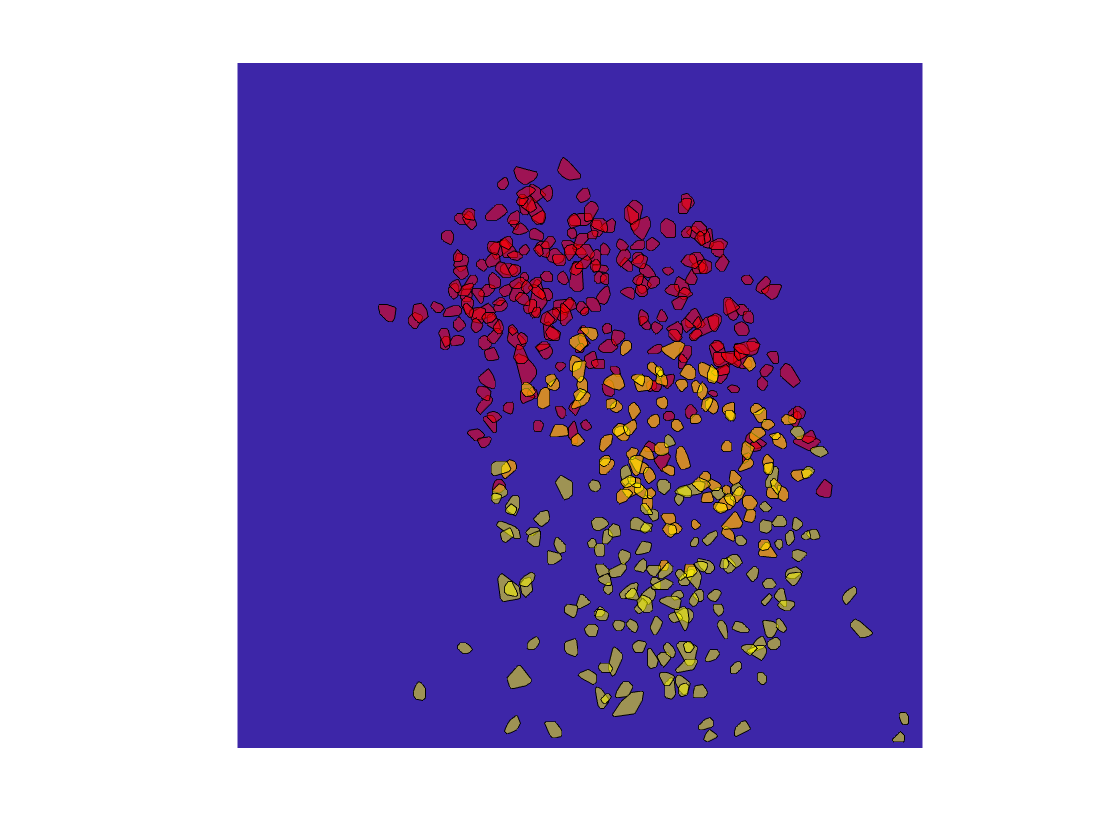

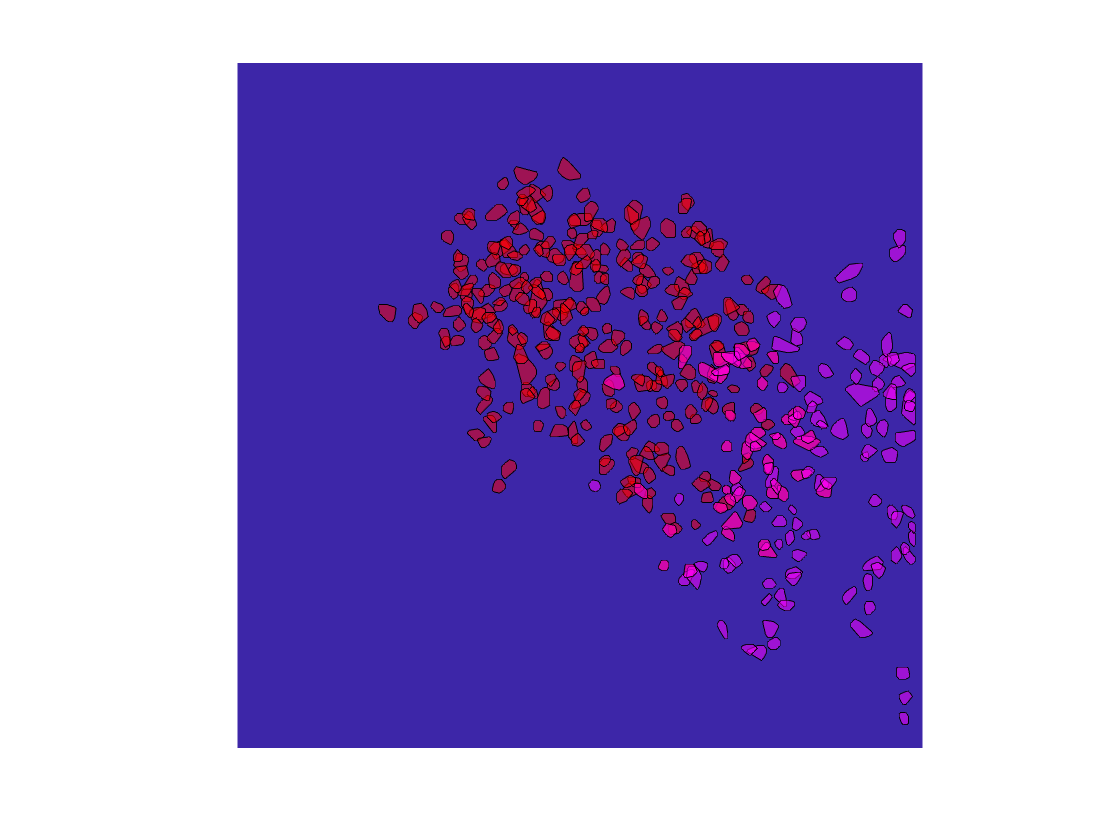

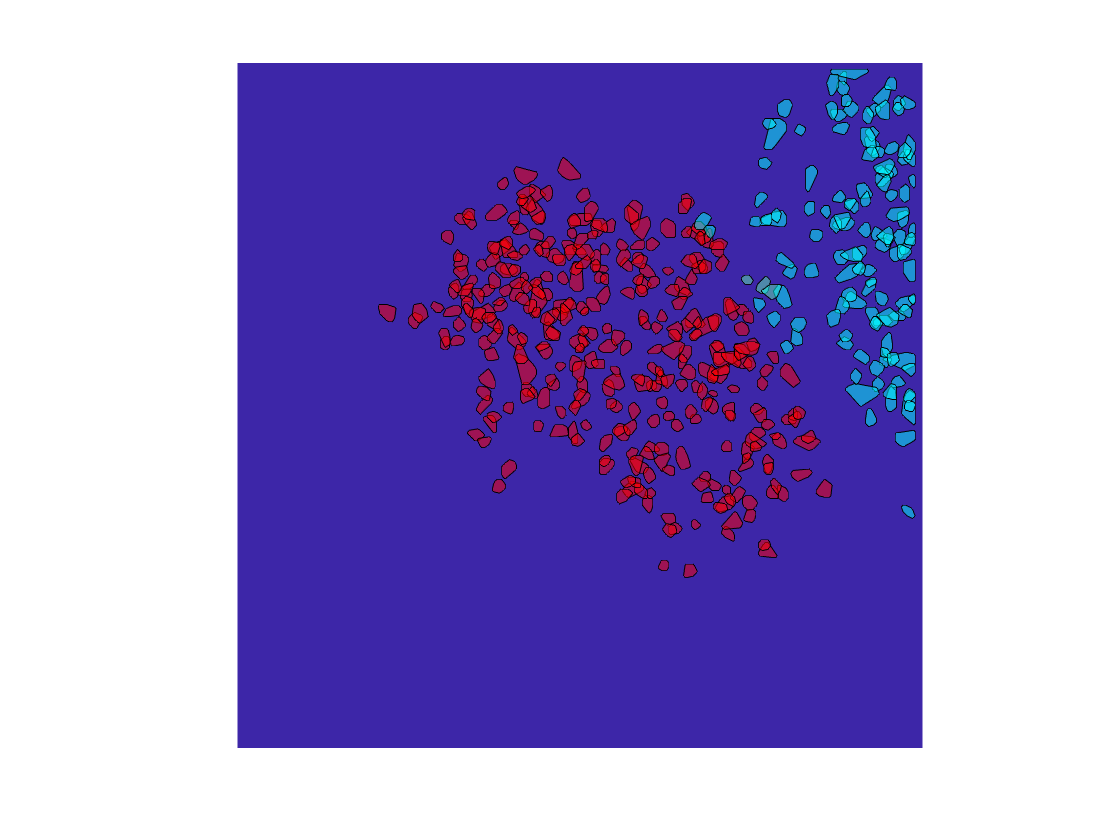

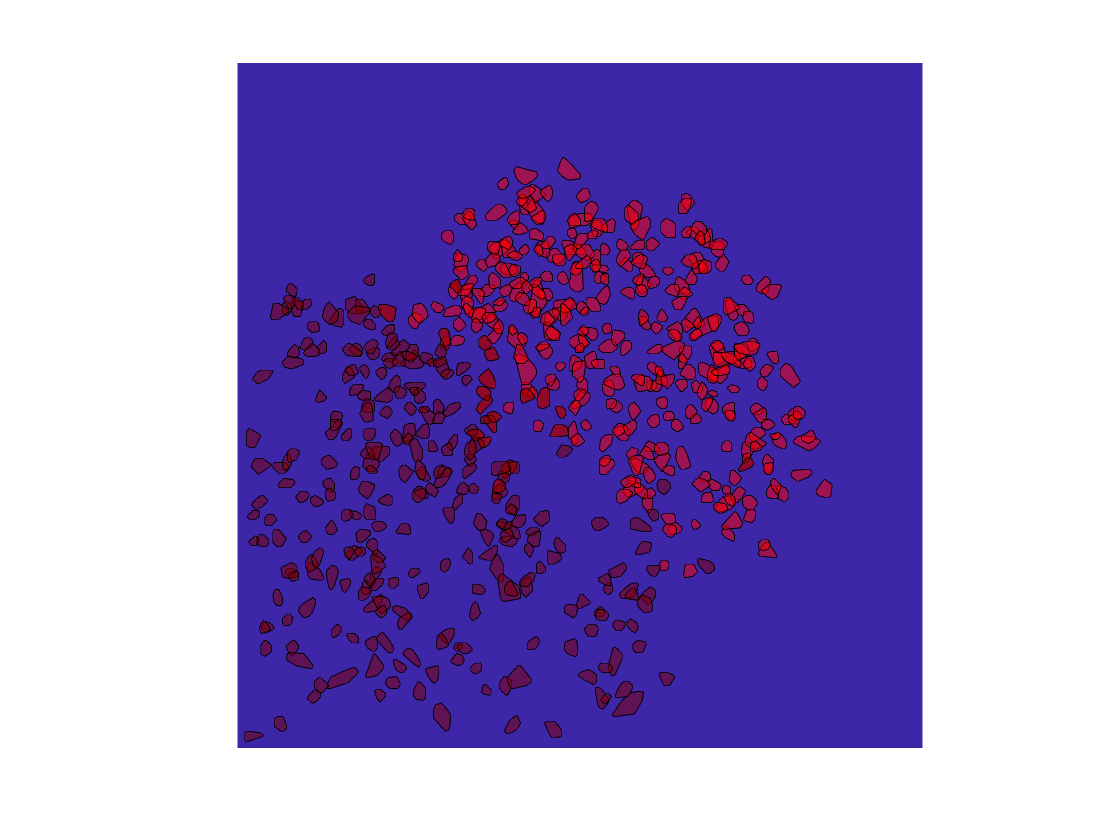

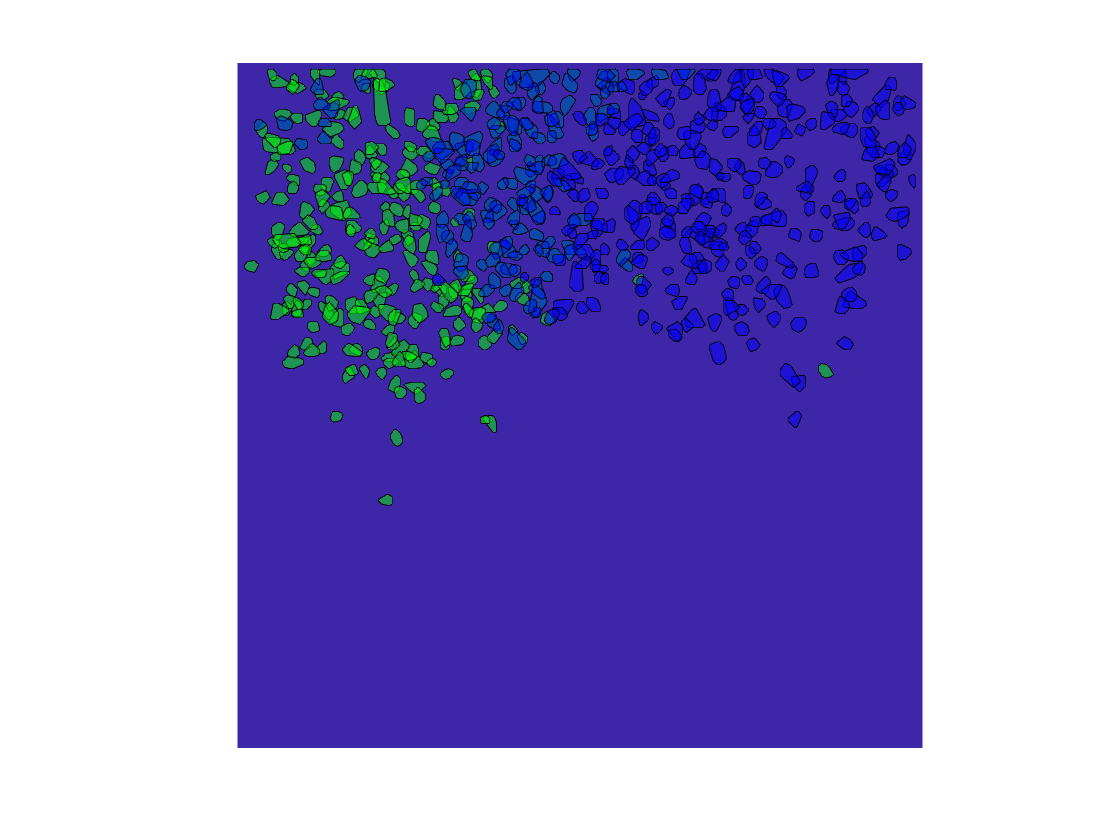

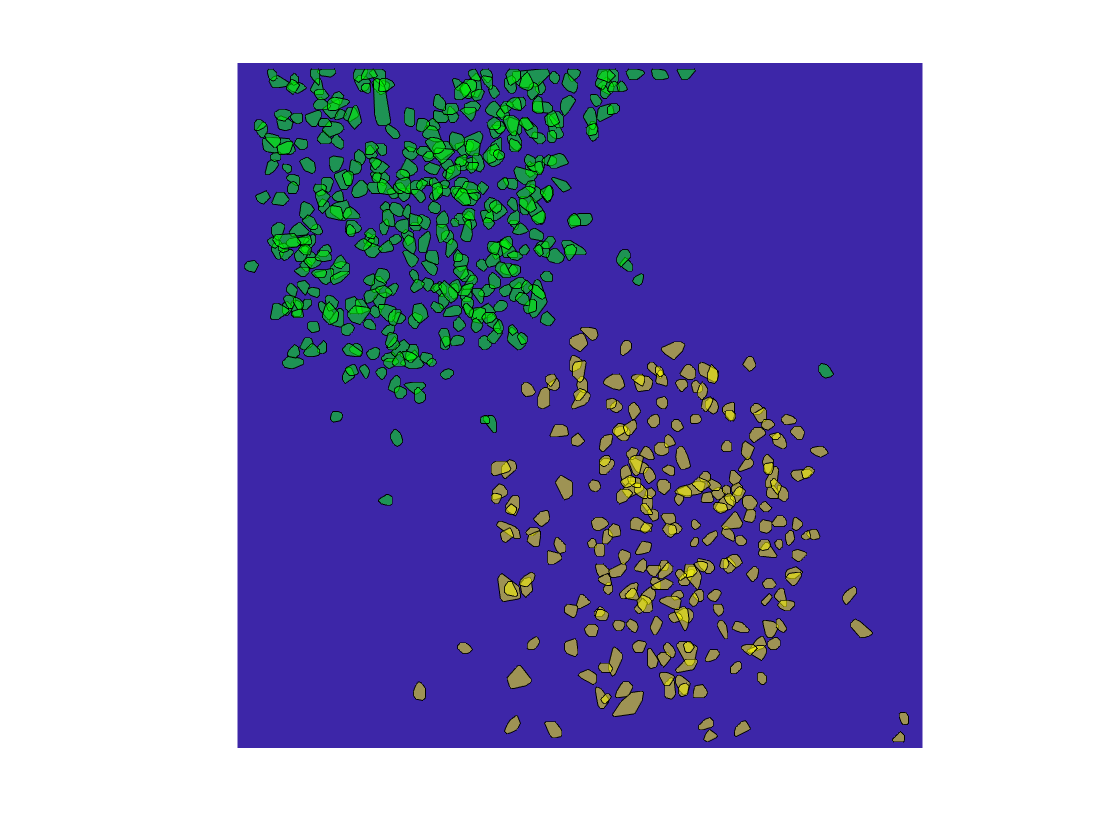

assembly=assembly_nonortho;
% assembly=assemblyraw;

% figure
% image(background);
% background=zeros(512,512);
for numa=1:nbassemblies-1

for num=numa+1:nbassemblies
figure
image(background);
background=zeros(512,512);
    for n=cell2mat(assembly(numa))
            x=cell2mat(outline_gcampx(n));
            y=cell2mat(outline_gcampy(n));
            sorted_indices = convhull(x, y); 
            x = x(sorted_indices);
            y = y(sorted_indices);
            patch(x, y,colors(numa,:),'FaceAlpha', 0.5)
             % patch(x, y,'w','FaceAlpha', 0.5,'EdgeColor',colors(num,:),'LineWidth',1)
            % text(max(x),max(y),num2str(n),"FontSize",8,"Color",'w')
            % plot(x, y, '.', 'MarkerSize', 4,"Color",col);
    end
        for n=cell2mat(assembly(num))
            x=cell2mat(outline_gcampx(n));
            y=cell2mat(outline_gcampy(n));
            sorted_indices = convhull(x, y); 
            x = x(sorted_indices);
            y = y(sorted_indices);
            patch(x, y,colors(num,:),'FaceAlpha', 0.5)
             % patch(x, y,'w','FaceAlpha', 0.5,'EdgeColor',colors(num,:),'LineWidth',1)
            % text(max(x),max(y),num2str(n),"FontSize",8,"Color",'w')
            % plot(x, y, '.', 'MarkerSize', 4,"Color",col);
    end
axis off
axis image
    % hold on
end
end

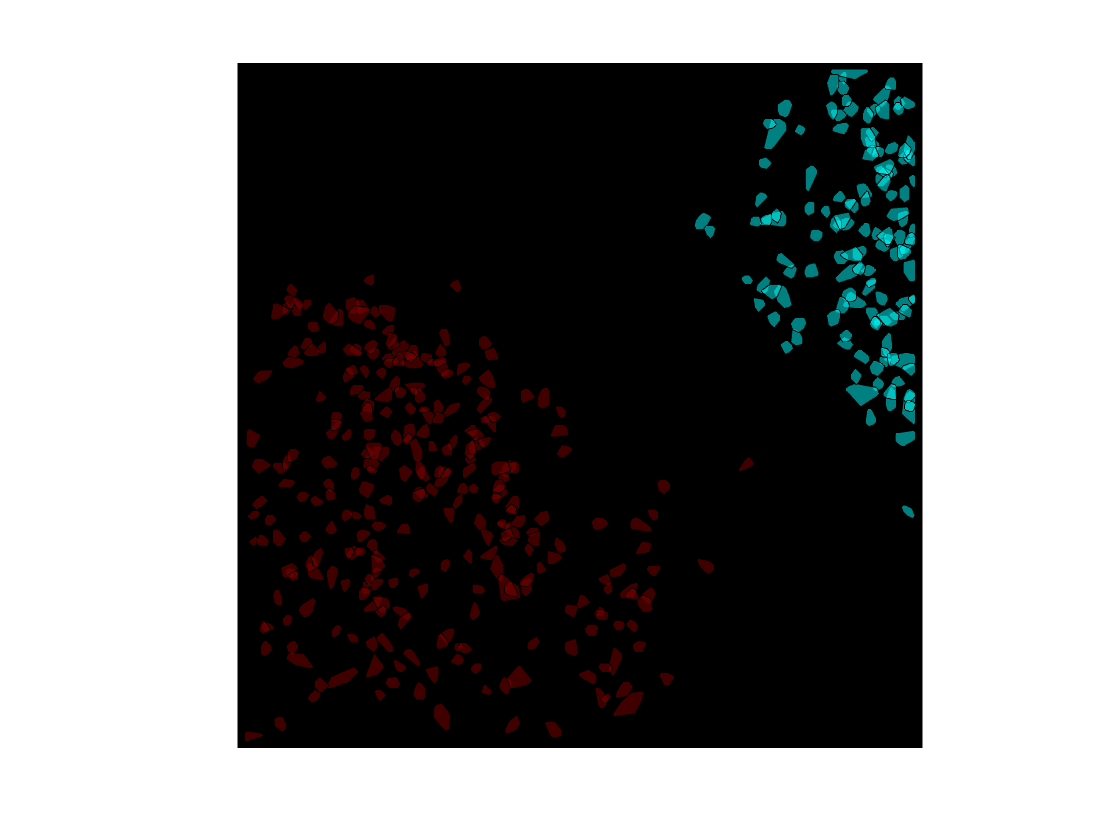

colormap (gray)
axis off
axis image

% mdl = fitlm(X_train, Y_train);